# Modelling - Decision Tree & K-Nearest Neighbor

## 0) Setup

Clear workspace, load datasets with different preprocessings and convert to matrices

clear; clc; % Clear workspace
rng(1) % set seed for reproducability

% Load baseline train and test data
train = readtable('train.csv');
test = readtable('test.csv');

train = train{:,:};  % Convert to matrix
test = test{:,:};

X_train = train(:, 2:end); % Split into target and features 
y_train = train(:, 1);
X_test = test(:, 2:end);
y_test = test(:, 1);

% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

## 1) Train / Test Baseline Models

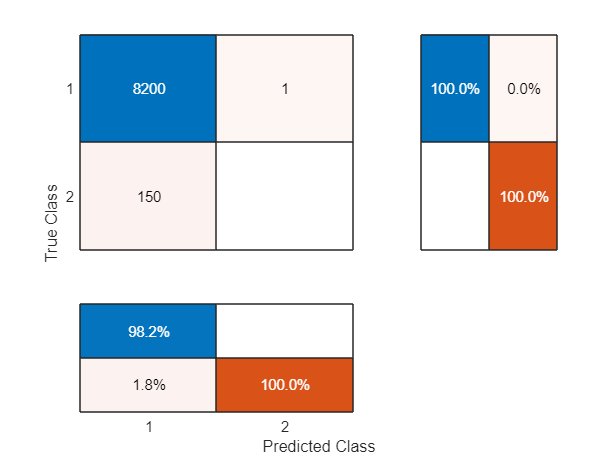

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

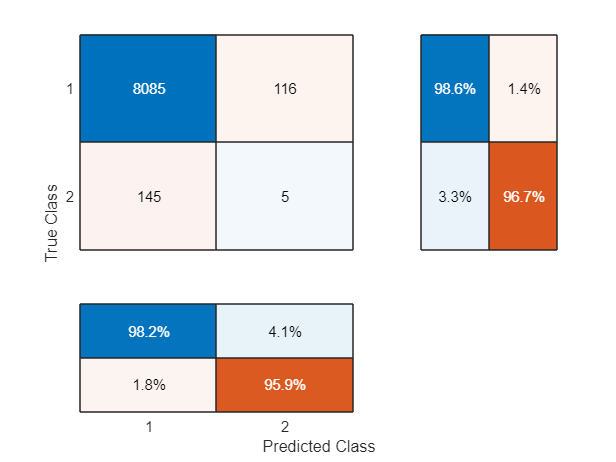

accuracy = 0.9687

precision = 0.0413

recall = 0.0333

specificity = 0.9859

fb = 0.0369

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Standardize', 1, 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

## 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy)

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
ParamsDT = [MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
ParamsKNN = [n; dst];

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014908 |     0.92852 |    0.014908 |    0.014908 |           22 |            3 |
|    2 | Best   |    0.014759 |       0.526 |    0.014759 |     0.01476 |            3 |           30 |
|    3 | Accept |    0.014849 |     0.60962 |    0.014759 |    0.014759 |            6 |            2 |
|    4 | Accept |    0.014759 |     0.65031 |    0.014759 |    0.014759 |           12 |           29 |
|    5 | Accept |    0.014759 |     0.82031 |    0.014759 |    0.014759 |           29 |           14 |
|    6 | Accept |    0.014789 |     0.71416 |    0.014759 |    0

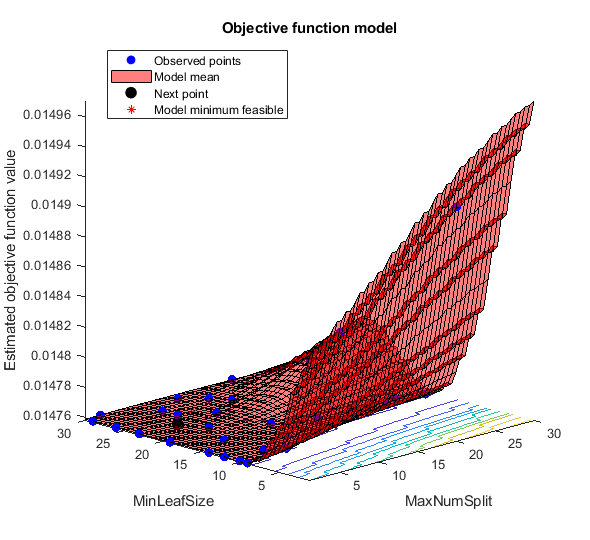

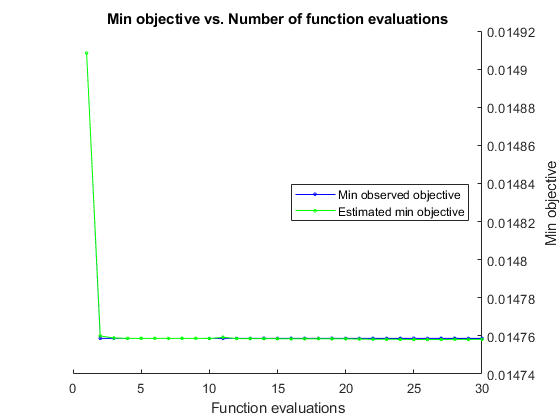


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 40.416 seconds
Total objective function evaluation time: 19.6702

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         3             30     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.526

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         1             10     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.40433



% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

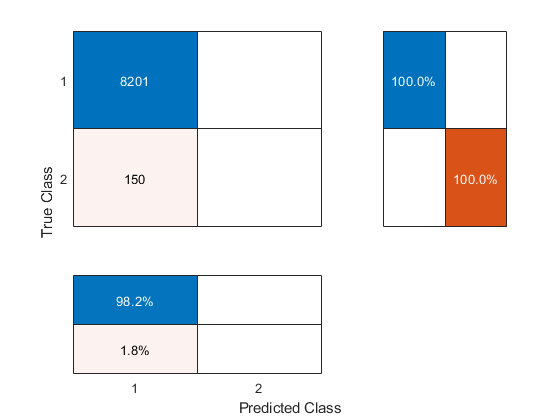

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014759 |      4.7135 |    0.014759 |    0.014759 |            7 |    euclidean |
|    2 | Accept |    0.014759 |      4.6555 |    0.014759 |    0.014759 |           13 |       cosine |
|    3 | Accept |    0.014759 |       4.732 |    0.014759 |    0.014759 |           19 |    euclidean |
|    4 | Accept |    0.016405 |      4.5025 |    0.014759 |     0.01517 |            3 |       cosine |
|    5 | Accept |    0.014759 |      4.8204 |    0.014759 |    0.014759 |           15 |    euclidean |
|    6 | Accept |    0.014759 |      4.7536 |    0.014759 |    0

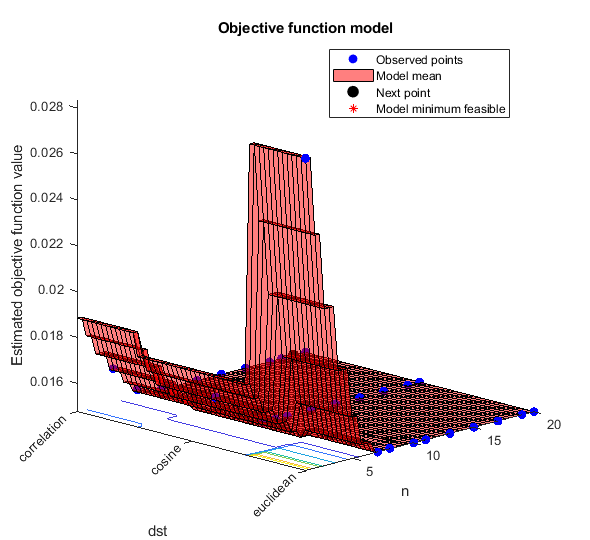

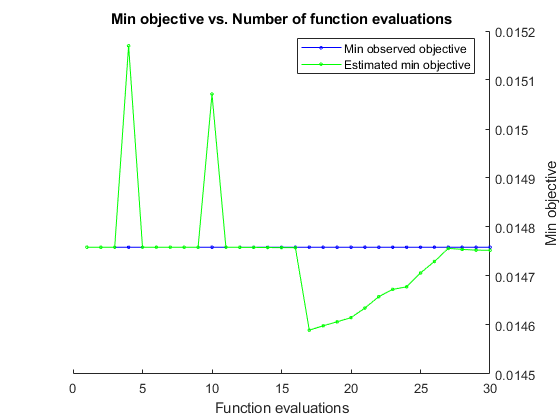


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 164.7738 seconds
Total objective function evaluation time: 143.1645

Best observed feasible point:
    n       dst   
    _    _________

    7    euclidean

Observed objective function value = 0.014759
Estimated objective function value = 0.014773
Function evaluation time = 4.7135

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    8    cosine

Estimated objective function value = 0.014753
Estimated function evaluation time = 4.7126



% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.40857 |           1 |           1 |            2 |           23 |
|    2 | Accept |           1 |     0.78286 |           1 |           1 |           28 |           11 |
|    3 | Accept |           1 |     0.53052 |           1 |           1 |            7 |           21 |
|    4 | Accept |           1 |     0.79361 |           1 |           1 |           21 |            3 |
|    5 | Accept |           1 |     0.80129 |           1 |           1 |           25 |           24 |
|    6 | Accept |           1 |     0.80006 |           1 |     

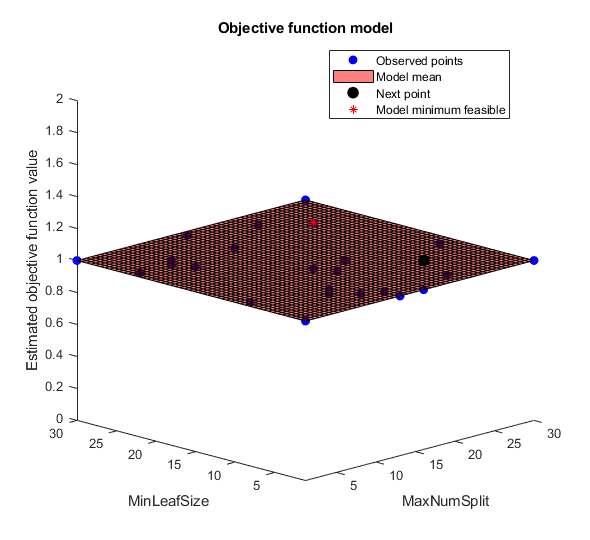

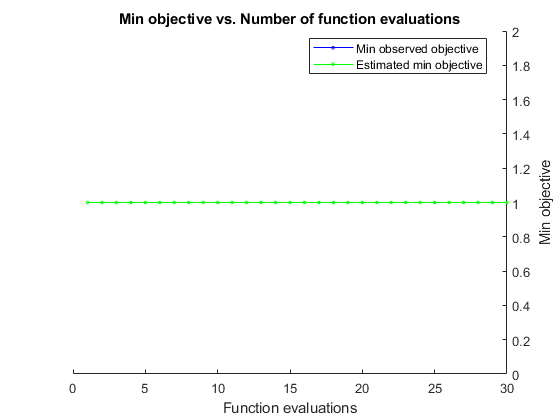


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 42.9367 seconds
Total objective function evaluation time: 21.0221

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         2             23     

Observed objective function value = 1
Estimated objective function value = 1
Function evaluation time = 0.40857

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         2             23     

Estimated objective function value = 1
Estimated function evaluation time = 0.45444



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.96367 |      4.7414 |     0.96367 |     0.96367 |            1 |       cosine |
|    2 | Accept |           1 |      4.8648 |     0.96367 |     0.96551 |           19 |       cosine |
|    3 | Accept |     0.99599 |      4.7977 |     0.96367 |     0.97483 |            5 |       cosine |
|    4 | Accept |           1 |      4.9461 |     0.96367 |     0.97159 |           14 |    euclidean |
|    5 | Accept |           1 |      4.7443 |     0.96367 |      0.9696 |           17 |  correlation |
|    6 | Accept |           1 |      4.8797 |     0.96367 |     

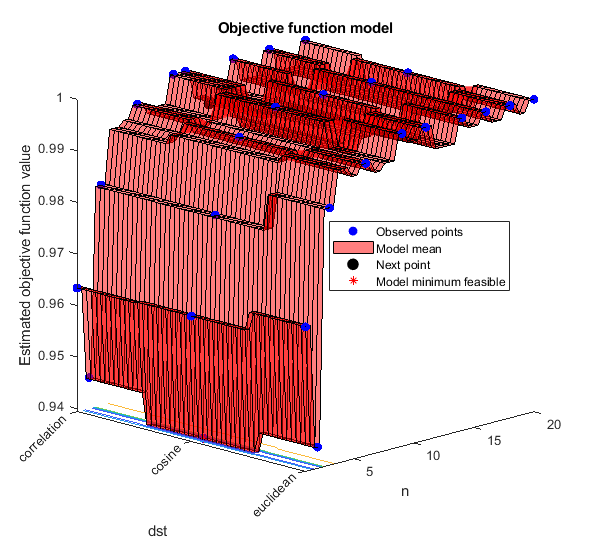

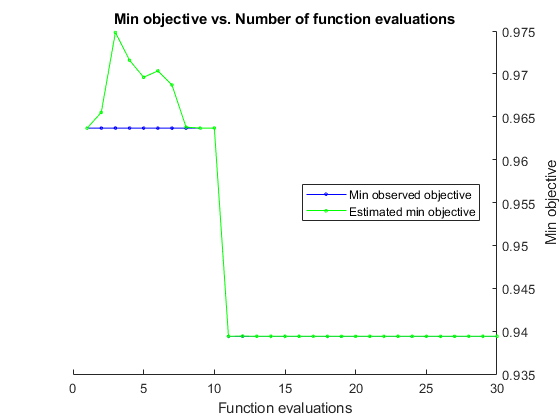


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 163.6325 seconds
Total objective function evaluation time: 143.9942

Best observed feasible point:
    n     dst  
    _    ______

    2    cosine

Observed objective function value = 0.93939
Estimated objective function value = 0.9394
Function evaluation time = 4.6958

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    2    cosine

Estimated objective function value = 0.9394
Estimated function evaluation time = 4.7418



% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

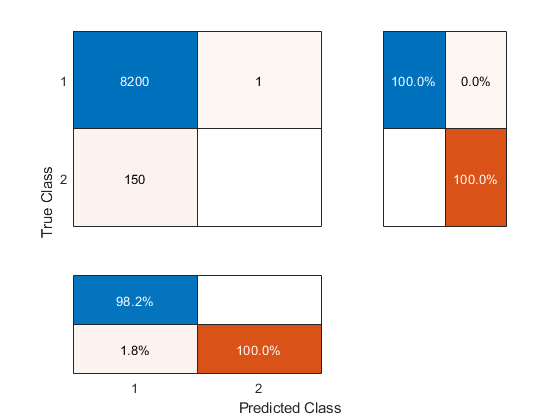

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta)

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 20, 'Stratify', true);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.52275 |           1 |           1 |            6 |            2 |
|    2 | Accept |           1 |     0.62193 |           1 |           1 |            8 |           18 |
|    3 | Accept |           1 |     0.91553 |           1 |           1 |           22 |           23 |
|    4 | Accept |           1 |     0.87017 |           1 |           1 |           14 |           19 |
|    5 | Accept |           1 |     0.90119 |           1 |           1 |           17 |           27 |
|    6 | Accept |           1 |     0.84098 |           1 |     

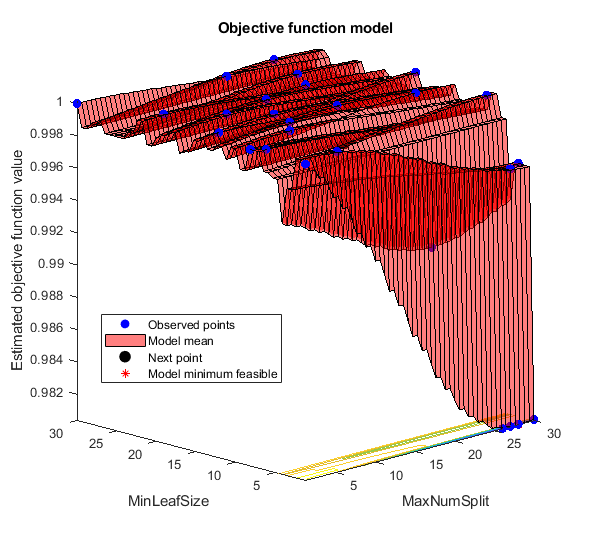

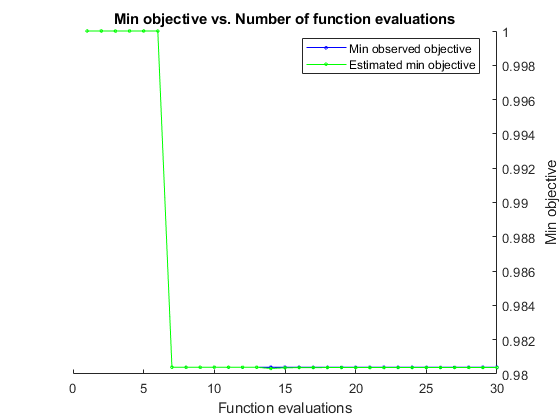


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 42.7554 seconds
Total objective function evaluation time: 22.5581

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26              1     

Observed objective function value = 0.98039
Estimated objective function value = 0.98044
Function evaluation time = 1.1282

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        28              1     

Estimated objective function value = 0.98038
Estimated function evaluation time = 0.90285



% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 4a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

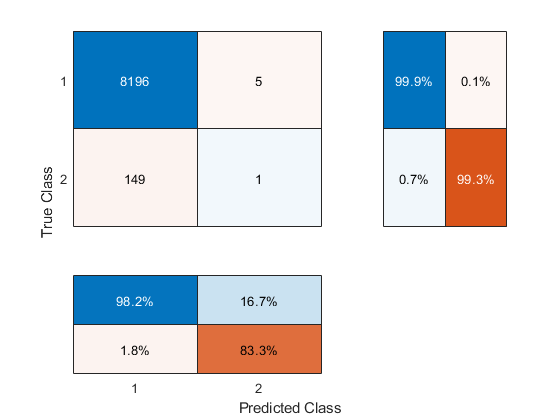

accuracy = 0.9816

precision = 0.1667

recall = 0.0067

specificity = 0.9994

fb = 0.0128


% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |      4.7178 |           1 |           1 |           19 |  correlation |
|    2 | Accept |           1 |      5.0856 |           1 |           1 |           15 |    euclidean |
|    3 | Accept |           1 |      4.8653 |           1 |           1 |           16 |       cosine |
|    4 | Best   |     0.98185 |      4.7048 |     0.98185 |     0.98187 |            3 |       cosine |
|    5 | Accept |           1 |      4.9325 |     0.98185 |     0.98185 |           18 |    euclidean |
|    6 | Accept |           1 |      4.7178 |     0.98185 |     

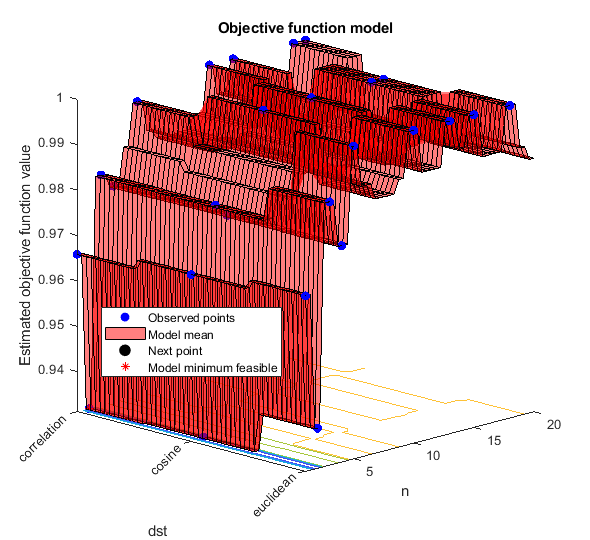

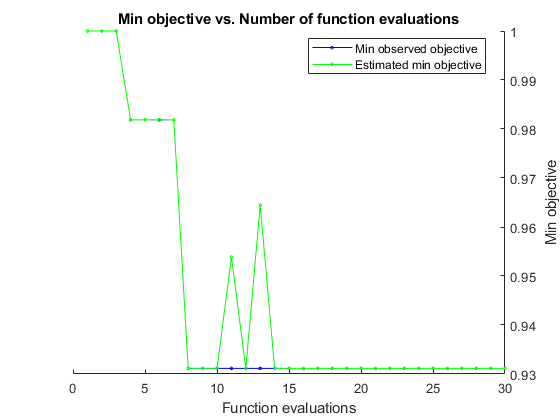


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 166.0873 seconds
Total objective function evaluation time: 144.5904

Best observed feasible point:
    n        dst    
    _    ___________

    2    correlation

Observed objective function value = 0.93116
Estimated objective function value = 0.93116
Function evaluation time = 4.6399

Best estimated feasible point (according to models):
    n        dst    
    _    ___________

    2    correlation

Estimated objective function value = 0.93116
Estimated function evaluation time = 4.7097



% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
% 4b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat); % see helper function

% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 5) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE)

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 20);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.12857 |      1.1478 |     0.12857 |     0.12857 |            2 |           23 |
|    2 | Best   |    0.086925 |      1.5559 |    0.086925 |    0.088999 |           28 |           11 |
|    3 | Accept |     0.11402 |      1.1404 |    0.086925 |    0.088011 |            7 |           21 |
|    4 | Accept |    0.087833 |      1.5818 |    0.086925 |    0.086924 |           21 |            3 |
|    5 | Best   |    0.086924 |      1.8767 |    0.086924 |    0.086882 |           25 |           24 |
|    6 | Accept |    0.099825 |      1.3088 |    0.086924 |    0

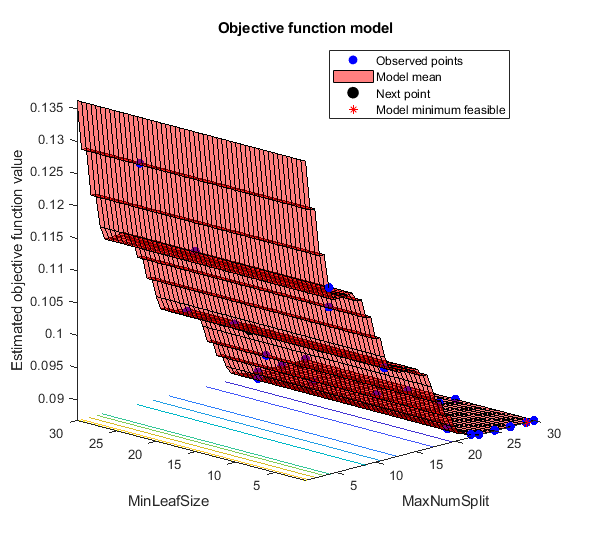

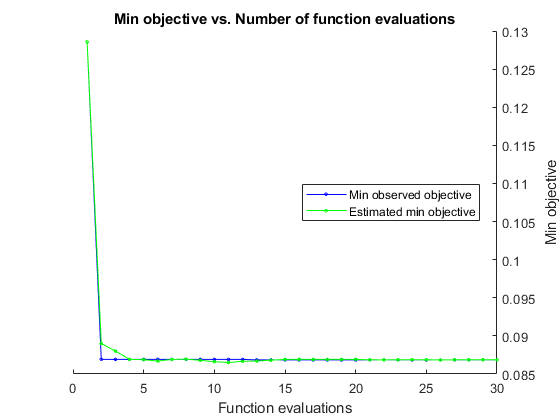


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 65.5337 seconds
Total objective function evaluation time: 45.8508

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.086847
Estimated objective function value = 0.086898
Function evaluation time = 1.5556

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29             16     

Estimated objective function value = 0.086862
Estimated function evaluation time = 1.5846



% 5a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 5a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

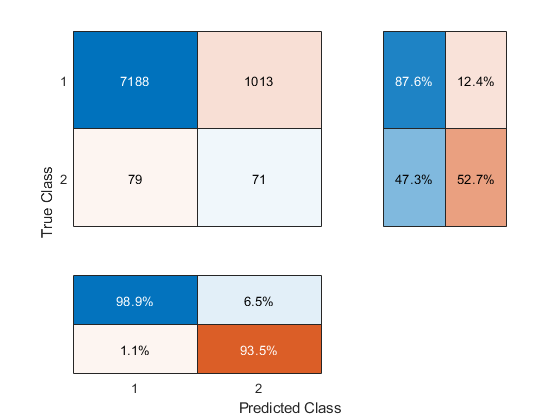

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.1151


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.015038 |      18.181 |    0.015038 |    0.015038 |            1 |       cosine |
|    2 | Accept |    0.020325 |      18.677 |    0.015038 |    0.015611 |           19 |       cosine |
|    3 | Best   |    0.012479 |      18.433 |    0.012479 |     0.01248 |            5 |       cosine |
|    4 | Accept |    0.017812 |      19.196 |    0.012479 |     0.01248 |           14 |    euclidean |
|    5 | Accept |    0.019498 |      19.902 |    0.012479 |     0.01248 |           17 |  correlation |
|    6 | Accept |    0.015094 |      20.515 |    0.012479 |     

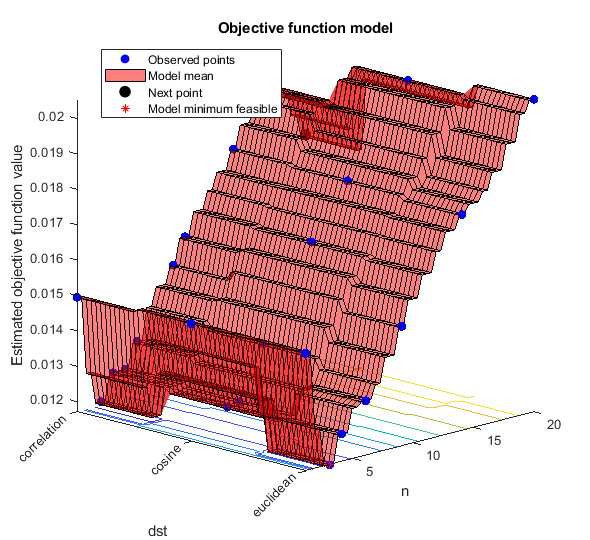

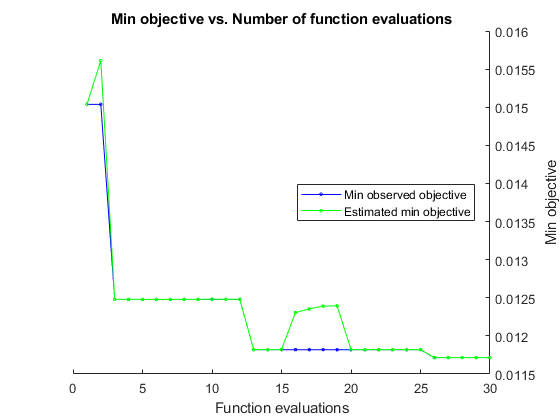


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 729.011 seconds
Total objective function evaluation time: 699.3772

Best observed feasible point:
    n       dst   
    _    _________

    3    euclidean

Observed objective function value = 0.011714
Estimated objective function value = 0.011715
Function evaluation time = 19.7496

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    3    euclidean

Estimated objective function value = 0.011715
Estimated function evaluation time = 22.9321



% 5b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 5b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

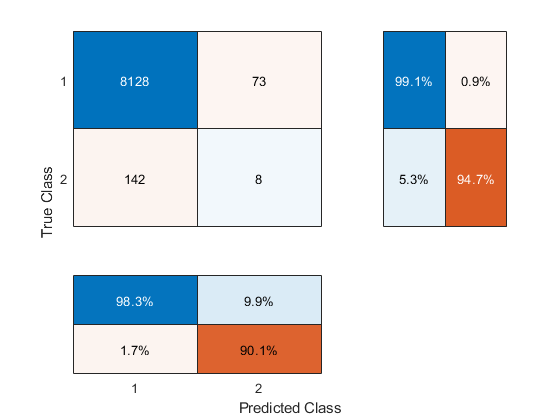

accuracy = 0.9743

precision = 0.0988

recall = 0.0533

specificity = 0.9911

fb = 0.0693


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.11832 |      1.5402 |     0.11832 |     0.11832 |            9 |           20 |
|    2 | Best   |     0.10595 |      1.5122 |     0.10595 |     0.10686 |           14 |            8 |
|    3 | Best   |    0.090395 |      1.8144 |    0.090395 |    0.090397 |           21 |           21 |
|    4 | Accept |     0.13821 |     0.88659 |    0.090395 |    0.090408 |            2 |            2 |
|    5 | Accept |     0.12026 |        1.17 |    0.090395 |    0.090397 |            4 |           25 |
|    6 | Accept |     0.12026 |      1.1988 |    0.090395 |    0

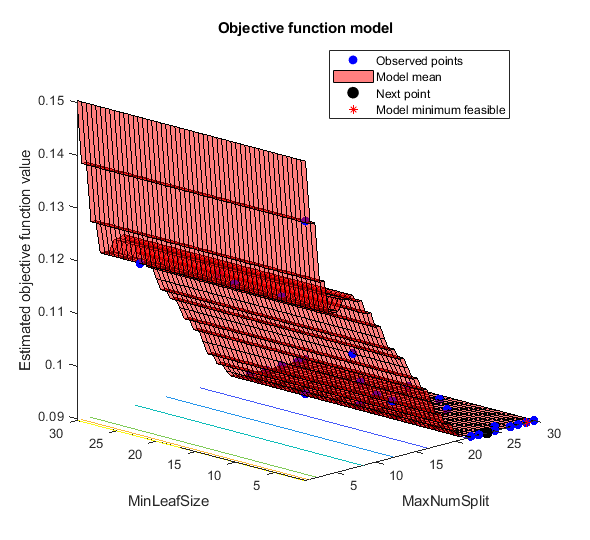

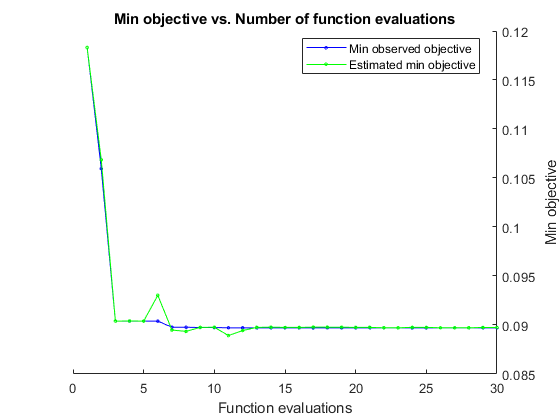


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 68.5799 seconds
Total objective function evaluation time: 49.3431

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.089712
Estimated objective function value = 0.089761
Function evaluation time = 1.8373

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        27              1     

Estimated objective function value = 0.08975
Estimated function evaluation time = 1.7687



% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.1151

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.012412 |      19.325 |    0.012412 |    0.012412 |            4 |       cosine |
|    2 | Accept |    0.012549 |      19.445 |    0.012412 |    0.012481 |            4 |  correlation |
|    3 | Accept |    0.020723 |      20.563 |    0.012412 |    0.012417 |           20 |    euclidean |
|    4 | Accept |    0.015192 |      19.949 |    0.012412 |    0.012413 |            9 |  correlation |
|    5 | Accept |    0.019644 |      20.297 |    0.012412 |    0.012413 |           17 |  correlation |
|    6 | Accept |    0.017912 |      35.621 |    0.012412 |    0

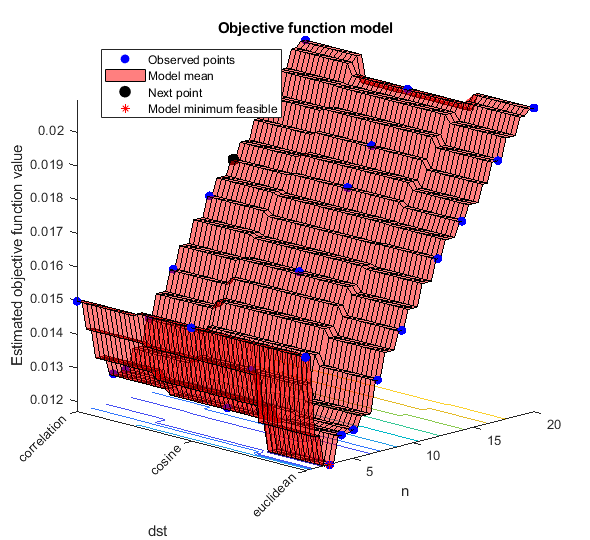

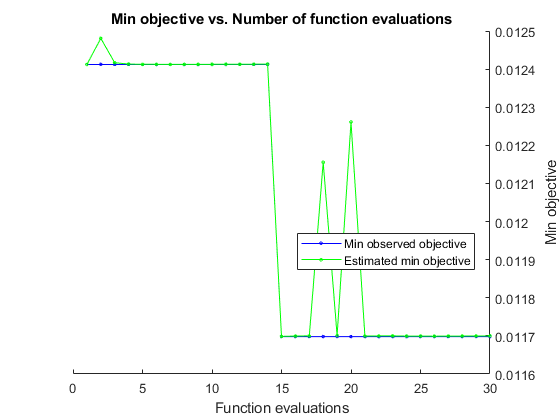


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 649.5574 seconds
Total objective function evaluation time: 624.8277

Best observed feasible point:
    n       dst   
    _    _________

    3    euclidean

Observed objective function value = 0.011698
Estimated objective function value = 0.0117
Function evaluation time = 20.0229

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    3    euclidean

Estimated objective function value = 0.0117
Estimated function evaluation time = 20.6605



% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9743

precision = 0.0988

recall = 0.0533

specificity = 0.9911

fb = 0.0693

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', cv_part, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 